% Shiqi Su
% MATH0033 Numerical Methods Computational Homework 1

## Set up

clear all, close all,clc
format long, format compact
fs=16;
set(groot,'defaulttextfontsize',fs);
set(groot,'defaultaxesfontsize',fs);
set(groot,'defaultLineLineWidth',2)      
set(groot,'defaultContourLineWidth',2) 
set(0,'DefaultLegendAutoUpdate','off') 

## Excersise_1_(a)

Bisection Method(choose interval [-pi/2,3]

nmax=30;
tol=1e-10;

f=@(x)x/2-sin(x)+pi/6-sqrt(3)/2;
x=linspace(-pi/2,3,100);
figure
plot(x,f(x))
grid on
xlabel('x')
ylabel('f(x)')
title('bisection method')
hold on

[zero,res,niter,itersb]=bisection(f,-pi/2,3,tol,nmax)

bisection stopped without converging to the desired tolerance because the maximum number of iterations was reached


zero =    2.246005587489026

res =     -2.035176804859873e-09

niter =     30

itersb =    0.714601836602552
   1.857300918301276
   2.428650459150638
   2.142975688725957
   2.285813073938297
   2.214394381332127
   2.250103727635212
   2.232249054483670
   2.241176391059441
   2.245640059347327


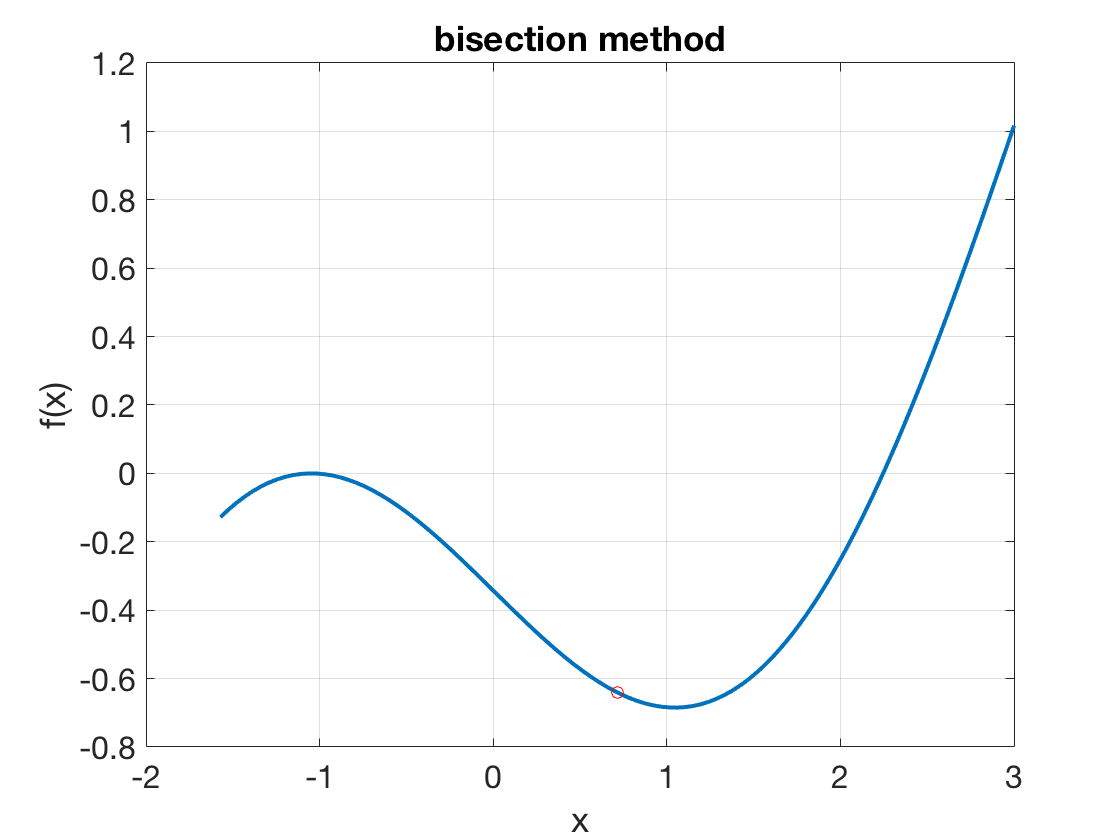

for i=1:10
      scatter(itersb(i,1),f(itersb(i,1)),'r')   % Plot the first 10 iterates from bisection
    pause                                     % pausing after each one
end

To conclude, one of the roots approximated by bisection method is about 2.2460

## Excersise_1_(b) Newton Method

tol=1e-10;
df=@(x)1/2-cos(x);
f=@(x)x/2-sin(x)+pi/6-sqrt(3)/2;
tol=1e-10;
nmax=30;
x_alpha=pi;
x_beta=-pi/2;
[zero,res,niter,itersn]=newton(f,df,x_alpha,tol,nmax)

zero =    2.246005589297974

res =      0

niter =      5

itersn =    3.141592653589793
   2.322679521183955
   2.247862901050224
   2.246006783255555
   2.246005589298468
   2.246005589297974


[zero,res,niter,itersn]=newton(f,df,x_beta,tol,nmax)

zero =   -1.047197557006185

res =      0

niter =     27

itersn =   -1.570796326794897
  -1.315146743627720
  -1.183631832053614
  -1.116174561731184
  -1.081897101040887
  -1.064602959203221
  -1.055914539391675
  -1.051559664465138
  -1.049379518712337
  -1.048288763440561


The solution of $f\left(x\right)=0$ is $\alpha =2\ldotp 24601$and $\beta =-1\ldotp 04720$. And the iteration for$\;\alpha$ is 5 , for  $\beta$ is 27. The difference in number of iterations is because of difference convergence rate. $f\prime \left(\alpha \right)\not= 0\;$and twice differentiable in the interval, so it is quadratic convergence. $f\prime \left(\beta \right)=0\;$which means linear convergence.

## Excersise_1_(c):Modified Newton Method

f=@(x)x/2-sin(x)+pi/6-sqrt(3)/2;
df=@(x)1/2-cos(x);
phi=@(x)x-2*f(x)/df(x);
x0=-pi/2;
[fixp,res,niter,itersfp1]=fixpoint(phi,x0,tol,nmax)

fixp =   -1.047197551213090

res =      0

niter =      4

itersfp1 =   -1.570796326794897
  -1.059497160460544
  -1.047211902180479
  -1.047197551213090
  -1.047197551213090


The number of iteration is 4.

## Excersise_2_(a)

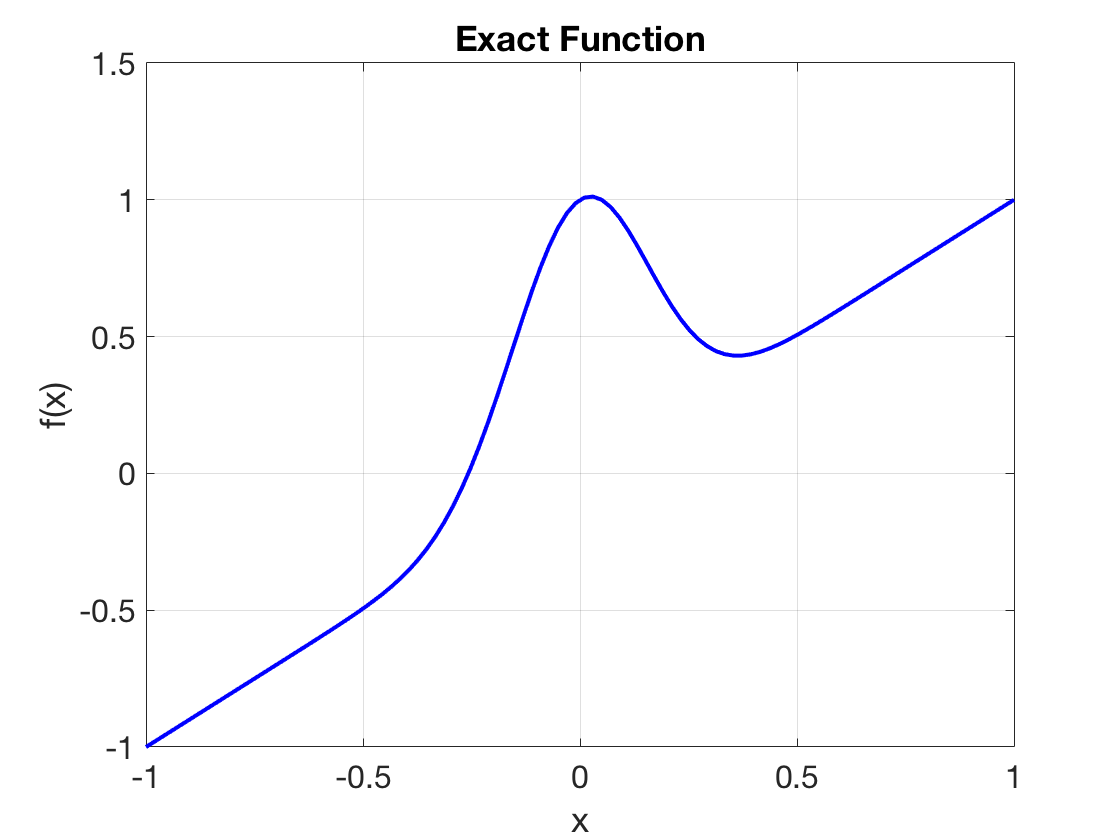

%define function and its derivative
f=@(x)x+exp(-20.*x.^2).*cos(x);
df=@(x)1+(-exp(-20*x^2)*sin(x)-cos(x)*exp(-20*x^2)*40*x);
%the range of x
x=linspace(-1,1,100);
%plot f(x)
figure
plot(x,f(x),'b','LineWidth',2)
grid on
xlabel('x');
ylabel('f(x)');
title('Exact Function')
hold on


% Apply Netwon Method to get first 10 iterations
tol=1e-10;
nmax=30;
x0=0;
[zero,res,niter,itersn]=newton(f,df,x0,tol,nmax);

newton stopped without converging to the desired tolerance because the maximum number of iterations was reached


disp('value of 10 first iteration')

value of 10 first iteration


disp(itersn(1:10))

                   0
  -1.000000000000000
  -0.000000047393887
  -0.999998056854453
  -0.000000047397530
  -0.999998056705078
  -0.000000047397531
  -0.999998056705060
  -0.000000047397531
  -0.999998056705060


## what happens when k tends to infinity

f=@(x)x+exp(-20.*x.^2).*cos(x);
df=@(x)1+(-exp(-20*x^2)*sin(x)-cos(x)*exp(-20*x^2)*40*x);

x=linspace(-1,1,100);
% Apply Netwon Method to get first 10 iterations
tol=1e-10;
nmax=500;
[zero,res,niter,itersn_2_a]=newton(f,df,x0,tol,nmax);

newton stopped without converging to the desired tolerance because the maximum number of iterations was reached


disp('first 20 iterations')

first 20 iterations


disp(itersn(1:20))

                   0
  -1.000000000000000
  -0.000000047393887
  -0.999998056854453
  -0.000000047397530
  -0.999998056705078
  -0.000000047397531
  -0.999998056705060
  -0.000000047397531
  -0.999998056705060
  -0.000000047397531
  -0.999998056705060
  -0.000000047397531
  -0.999998056705060
  -0.000000047397531
  -0.999998056705060
  -0.000000047397531
  -0.999998056705060
  -0.000000047397531
  -0.999998056705060


It appears with oscillation and doesn't converge to roots. Because its convergence theory is for "local" convergence with initial guess $x_0\in[\alpha-\delta,\alpha+\delta]$,where $\delta$ is sufficently small. Far away from the root the method can have highly nontrivial dynamics.

## Excersise_2_(b) 

using bisection method to find a better starting point

f=@(x)x+exp(-20.*x.^2).*cos(x);
df=@(x)1+(-exp(-20*x^2)*sin(x)-cos(x)*exp(-20*x^2)*40*x);
% bisection with 5 iterations
nmax=5;
tol=1e-10;
[zero,res,niter,itersb]=bisection(f,-1,1,tol,nmax)

bisection stopped without converging to the desired tolerance because the maximum number of iterations was reached


zero =   -0.281250000000000

res =   -0.083769359550674

niter =      5

itersb =                    0
  -0.500000000000000
  -0.250000000000000
  -0.375000000000000
  -0.312500000000000
  -0.281250000000000


% use a better starting point found by bisection method
x0=zero;
nmax_2_b=30;
[zero,res,niter,itersn_2_b]=newton(f,df,x0,tol,nmax_2_b)

zero =   -0.257298150803993

res =      0

niter =      4

itersn_2_b =   -0.281250000000000
  -0.255700520291546
  -0.257291994886876
  -0.257298150711709
  -0.257298150803993


In conclusion, the root is -0.257298 with 4 iterations.